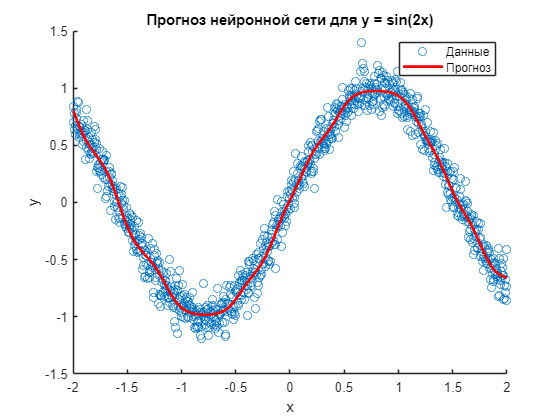

% Генерация данных для обучения
X = linspace(-2, 2, 1000)';
y = sin(2 * X) + 0.1 * randn(size(X));

% Создание и обучение нейронной сети
net = fitnet(10); % 10 нейронов в скрытом слое
net = train(net, X', y');

% Прогнозирование значений процесса
X_new = linspace(-2, 2, 100)';
y_pred = net(X_new');

% Визуализация результатов
figure;
scatter(X, y, 'DisplayName', 'Данные');
hold on;
plot(X_new, y_pred, 'r', 'LineWidth', 2, 'DisplayName', 'Прогноз');
title('Прогноз нейронной сети для y = sin(2x)');
xlabel('x');
ylabel('y');
legend('show');
hold off;